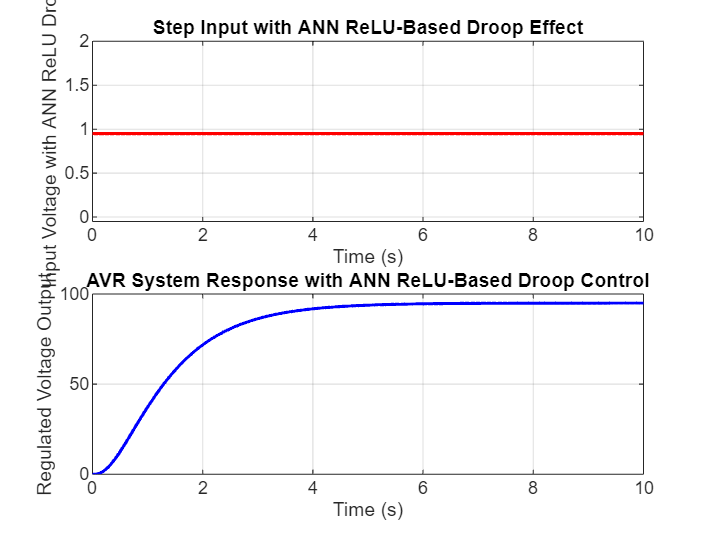

clc; clear; close all;

%% AVR System with ANN Droop - State Space Model

% Define system parameters
Ka = 10;  % Amplifier gain
Ta = 0.1; % Amplifier time constant
Ke = 1;   % Exciter gain
Te = 0.4; % Exciter time constant
Kg = 1;   % Generator gain
Tg = 1.0; % Generator time constant
Kr = 0.05; % Droop control gain

% Define state-space representation
% State variables: x1 = amplifier output, x2 = exciter output, x3 = generator output
A = [-1/Ta,  0,     0;
      Ka/Te, -1/Te, 0;
      0,     Ke/Tg, -1/Tg];

B = [Ka/Ta;  0;  0];  % Input matrix (voltage reference input)
C = [0, 0, Kg];  % Output matrix (regulated voltage output)
D = 0;  % Direct transmission matrix

% Create state-space system
sys = ss(A, B, C, D);

%% ANN-based Droop Control (Using ReLU)
ReLU = @(x) max(0, x);  % ReLU Activation Function
droop_gain = @(x) Kr * ReLU(x);  % ReLU-based ANN Droop function

% Define input signal (Step Response with ReLU-based Droop Control)
t = 0:0.01:10;  % Time vector
u = ones(size(t));  % Step input
u = u - droop_gain(u);  % Apply ReLU-based ANN droop control

% Simulate response
[y, t, x] = lsim(sys, u, t);

%% Plot Results
figure;
subplot(2,1,1);
plot(t, u, 'r', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Input Voltage with ANN ReLU Droop');
title('Step Input with ANN ReLU-Based Droop Effect');
grid on;

subplot(2,1,2);
plot(t, y, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Regulated Voltage Output');
title('AVR System Response with ANN ReLU-Based Droop Control');
grid on;